# Assignment Linear Program

clearvars;

## Read in the data

tbl = readtable("residential_electricity_data.csv");

## Charge and discharge limits

c =5;
lb = -c*ones(24, 1);
ub =  c*ones(24, 1);

## Capacity Limits

cap = 15;
A_1 = tril(ones(24, 24)) ;
b_1 = cap*ones(24, 1);

## Cant discharge battery below 0

A_2 = -1*tril(ones(24, 24));
b_2 = zeros(24, 1);

## Any energy exported is wasted, dont export

A_3 = -1*eye(24);
L = tbl.Load;
S = tbl.Generation;
b_3 = L-S;

## Add all the constraints to the same matrix

A = cat(1, A_1, A_2, A_3);
b = cat(1, b_1, b_2, b_3);

## Objective Function

n = tbl.Import;

## Solve

[B, fval] = linprog(n,A,b,[],[],lb,ub)

Optimal solution found.



B =     5.0000
    2.1600
   -2.4300
   -2.3700
   -2.3600
    3.7800
   -1.3600
   -0.2400
    0.8500
    2.0100


fval = -1.6810

## Work out "real" payment

net_load = L-S;
payment = fval + (net_load.' * n)

payment = 7.4860

## Plots

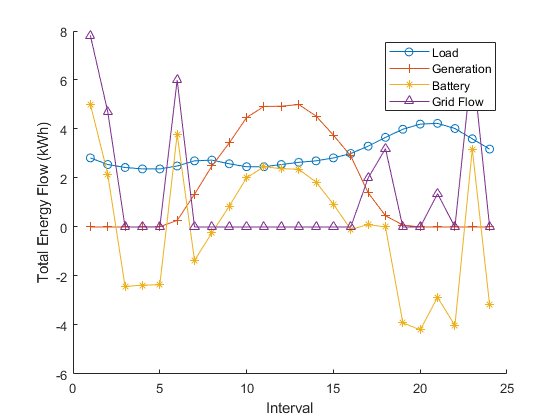

G = L-S+B;

time = 1:24;
hold on
legend
xlabel('Interval')
ylabel('Total Energy Flow (kWh)')
plot(time,tbl.Load, '-o','DisplayName','Load')
plot(time,tbl.Generation, '-+','DisplayName','Generation')
plot(time,B, '-*', 'DisplayName', 'Battery')
plot(time,G, '-^', 'DisplayName','Grid Flow')

% plot(time,n,'DisplayName','Import price')
% plot(time,(L-S),'DisplayName','Net Load')
% plot(time, cumsum(B),'DisplayName','Battery State')